## step 50 [deg] simulations for ss robust tracking


% simulate value with ss robust tracking and step 50 [deg] 

step_amplitude = 50;

data = sim("lab3_ss_robust_sim.slx");

t = data.ScopeData1.time;
tetha_h = data.ScopeData1.signals(1).values;  
tetha_d = data.ScopeData1.signals(2).values;
ref_signal = data.ScopeData1.signals(3).values;
% error = data.ScopeData1.signals(3).values;
% command_u =  data.ScopeData1.signals(4).values;

save("lab3_50_robust_ss.mat",'t','tetha_h','tetha_d','ref_signal');



## Stampa grafico

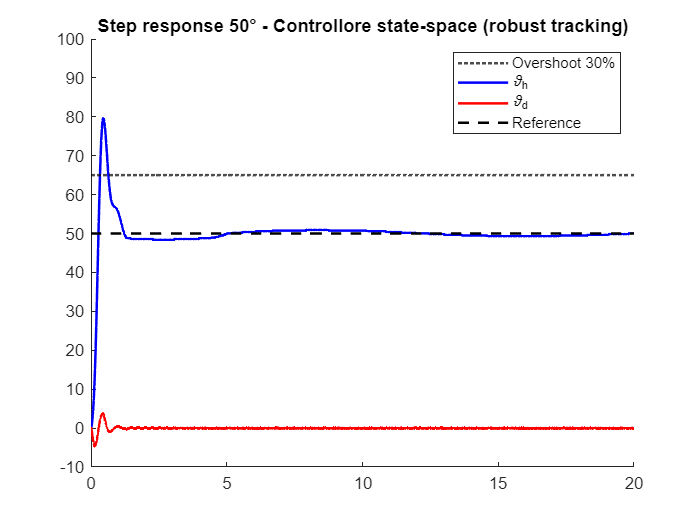


% grafico step 50 deg

load("lab3_50_robust_ss.mat");
figure;
% plot(t,ref,'k--');
yline(65, 'k:','LineWidth', 1.5, 'DisplayName', 'Overshoot 30%');
hold on 
plot(t,tetha_h,'b','LineWidth', 1.5, 'DisplayName', '\vartheta_h');
plot(t,tetha_d,'r','LineWidth', 1.5, 'DisplayName', '\vartheta_d');
plot(t,ref_signal,'k--','LineWidth', 1.5, 'DisplayName', 'Reference');
axis([0 20 -10 100])
title('Step response 50° - Controllore state-space (robust tracking)')
legend
hold off

#### Step response parameters


step_50_wind_up = stepinfo(tetha_h, t, 50, 'SettlingTimeThreshold', 0.05);
disp(step_50_wind_up);

         RiseTime: 0.1768
    TransientTime: 1.1259
     SettlingTime: 1.1259
      SettlingMin: 45.3600
      SettlingMax: 79.5600
        Overshoot: 59.1200
       Undershoot: 0
             Peak: 79.5600
         PeakTime: 0.4410

